*Copyright 2025 The MathWorks, Inc.*

# **EXERCISE 2 : 5G** **Intercell Interference Modeling**

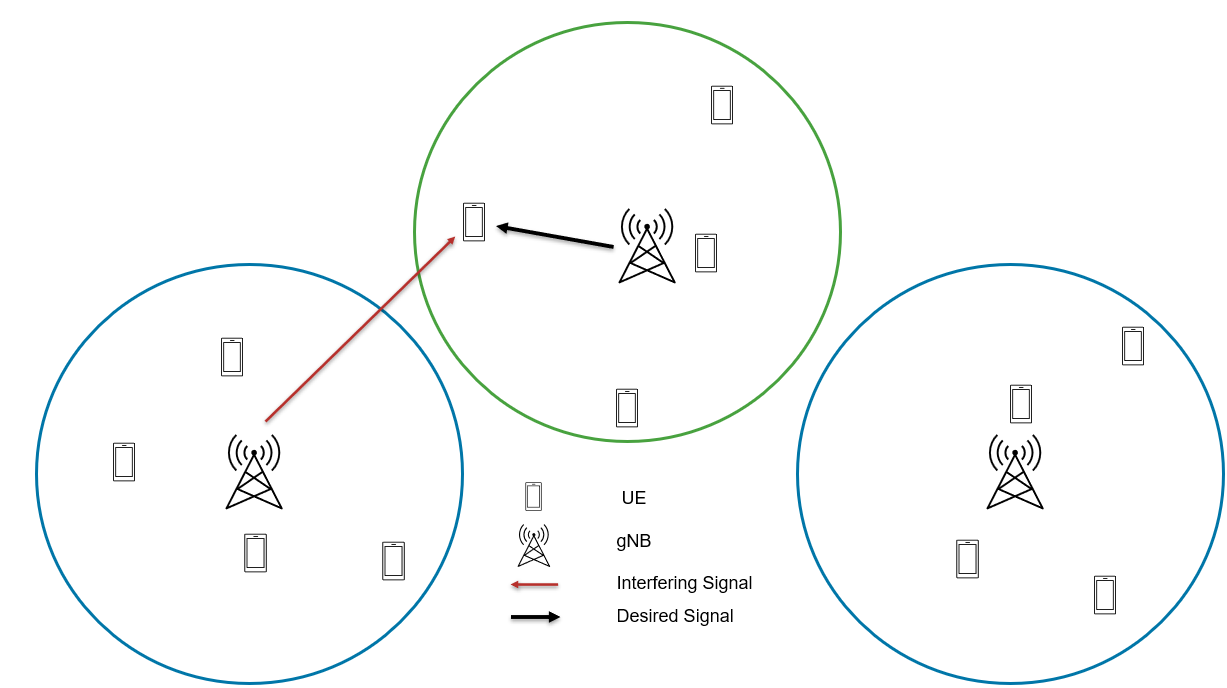

This excercise shows how to simulate a multicell interference scenario and measure the impact on network performance due to downlink (DL) intercell interference caused by nearby cells. The goals are:

- Model a multi-cell network scenario

- Analyze the impact on user throughput, particularly for users near the cell edge

- Visualize how channel conditions change as a result of inter-cell interference                            

wirelessnetworkSupportPackageCheck
all_figs = findall(0, 'type', 'figure');close(all_figs); % close all previous windows 
p = addpath(fullfile('.', 'Shared', 'Helpers'), fullfile('.', 'Shared', 'Utilities')); % Add path to helpers and utilities

#### Initialize Variables and Wireless Network Simulator

rng("default")                             % Reset the random number generator
numFrameSimulation = 5; % Simulation time in terms of number of 10 ms frames
% Calculate the simulation duration (in seconds)
simulationTime = numFrameSimulation*1e-2;
networkSimulator = wirelessNetworkSimulator.init;

#### Create and configure gNBs 

numCells = 3;
gNBs = cell(numCells,1);
gNBPositions = [1700 600 30; 3000 600 30; 2500 1500 30];
carrierFrequency = [2.5e9, 2.5e9, 2.5e9];
gNBNames = "gNB-" + (1:size(gNBPositions,1));
for cellIdx = 1:numCells
    gNBs{cellIdx}    = nrGNB(CarrierFrequency=carrierFrequency(cellIdx), ...
        Name=gNBNames(cellIdx), ...
        Position=gNBPositions(cellIdx,:), ...
        ChannelBandwidth=10e6, ...
        SubcarrierSpacing=30e3, ...
        TransmitPower=32, ...
        ReceiveGain=11, ...
        SRSPeriodicityUE=5);
    configureScheduler(gNBs{cellIdx},ResourceAllocationType=1);
end

#### Create and configure UEs, and set up interfering cells

numUEsPerCell = 4;
cellRadius = 500; % Radius of each cell (in meters)
uePositions = generateUEPositions(cellRadius,gNBPositions(1:2,:),numUEsPerCell);
UEs = cell(numCells,1);
for cellIdx = 1:numCells-1
    ueNames = "UE-" + (1:size(uePositions{cellIdx},1));
    UEs{cellIdx} = nrUE(Name=ueNames,Position=uePositions{cellIdx},ReceiveGain=11);
    connectUE(gNBs{cellIdx},UEs{cellIdx},FullBufferTraffic="DL")
end

#### Position the UEs within the cell of interest

controlUEPositions = false;
cellOfInterestIdx = 3; % Specify an integer value in the range [1, numCells]
if controlUEPositions
    distanceThreshold = 0.8; % fraction of cell radius
    sector =  6; % 1 to 8, represents a sector of 45 degrees
    uePos = generateUEPositions(cellRadius,gNBPositions(cellOfInterestIdx,:),numUEsPerCell,distanceThreshold,sector);
else
    uePos = generateUEPositions(cellRadius,gNBPositions(cellOfInterestIdx,:),numUEsPerCell);
end

# Task #1/2 Create, configure, and set up the cell of interest

ueNames = ["UE-1";"UE-2";"UE-3";"UE-4"];
UEs{cellOfInterestIdx} = nrUE(Name=ueNames,ReceiveGain=11,Position=uePos{1});
% Use connectUE() function to connect gNB of cell-2 to corresponding UEs
% Hint:Click the following link, and see the "Syntax" section.

[Help on connecting UEs to gNB  ](https://www.mathworks.com/help/5g/ref/nrgnb.connectue.html)

% Note : use the following values to start with
%    gNBs(cellOfInterestIdx) 
%    UEs{cellOfInterestIdx}  
%    FullBufferTraffic="off"

% Note on Full Buffer Traffic
% Full buffer traffic refers to a traffic model where the transmit buffer 
% is always full, i.e., the node continuously has data to send. 
% This model is particularly useful in network simulations for evaluating 
% MAC and PHY layer performance, as it removes variability introduced by 
% higher-layer traffic patterns.

% Enter your code here
connectUE(gNBs{cellOfInterestIdx}, UEs{cellOfInterestIdx},FullBufferTraffic="off");    

# Task #2/2 Configure a traffic model 

dataRate = 10e3; % in kbps
ontime = inf;
offtime = 0;

% Define traffic type
% Use networkTrafficOnOff() function to configure application layer traffic
% Write configuration in a variable named "traffic"
% Hint: Type "doc networkTrafficOnOff" in the MATLAB Command Window, and see the "Syntax" section.
% Note : use the following values to start with
% onTime = ontime
% OffTime = offtime
% DataRate = dataRate % in kpbs
% PacketSize = 1024
% GeneratePacket=true

  % <enter code below>
traffic = networkTrafficOnOff(OnTime=Inf, ...
    OffTime=0, ...
    DataRate=dataRate, ...
    PacketSize=1024, ...
    GeneratePacket=true);      % Configuration for periodic traffic

Time: 0.000819 s - Generated a periodic packet_1 of size 1024 bytes
Time: 0.001638 s - Generated a periodic packet_2 of size 1024 bytes
Time: 0.002458 s - Generated a periodic packet_3 of size 1024 bytes
Time: 0.003277 s - Generated a periodic packet_4 of size 1024 bytes
Time: 0.004096 s - Generated a periodic packet_5 of size 1024 bytes
Time: 0.004915 s - Generated a periodic packet_6 of size 1024 bytes
Time: 0.005734 s - Generated a periodic packet_7 of size 1024 bytes
Time: 0.006554 s - Generated a periodic packet_8 of size 1024 bytes
Time: 0.007373 s - Generated a periodic packet_9 of size 1024 bytes
Time: 0.008192 s - Generated a periodic packet_10 of size 1024 bytes
Time: 0.009011 s - Generated a periodic packet_11 of size 1024 bytes
Time: 0.009830 s - Generated a periodic packet_12 of size 1024 bytes
Time: 0.010650 s - Generated a periodic packet_13 of size 1024 bytes
Time: 0.011469 s - Generated a periodic packet_14 of size 1024 bytes
Time: 0.012288 s - Generated a periodic pac

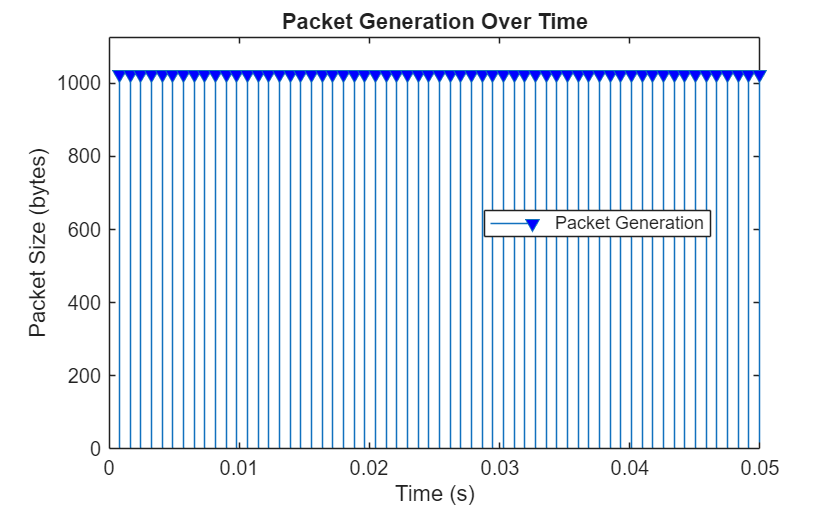

plotTrafficPattern(simulationTime,traffic)

#### Add uplink and downlink traffic 

% Add uplink traffic 
for i = 1:length(UEs{cellOfInterestIdx})
    traffic= networkTrafficOnOff(DataRate=dataRate,PacketSize=1024,GeneratePacket=true,OnTime=ontime,OffTime=offtime);
    addTrafficSource(UEs{cellOfInterestIdx}(i),traffic,"DestinationNode",gNBs{cellOfInterestIdx});
end
% Add downlink traffic 
for i = 1:length(UEs{cellOfInterestIdx})
    traffic= networkTrafficOnOff(DataRate=dataRate,PacketSize=1024,GeneratePacket=true,OnTime=ontime,OffTime=offtime);
    addTrafficSource(gNBs{cellOfInterestIdx},traffic,"DestinationNode",UEs{cellOfInterestIdx}(i));
end

#### Add gNBs and UEs to the network simulator

addNodes(networkSimulator,gNBs);
for cellIdx = 1:numCells
    addNodes(networkSimulator,UEs{cellIdx})
end

#### Add channel to the network simulator

channelModel = "3GPP TR 38.901";
if strcmp(channelModel,"3GPP TR 38.901")
    % Define scenario boundaries
    pos = [reshape([gNBPositions],3,[])];
    minX = min(pos(1,:));          % x-coordinate of the left edge of the scenario in meters
    minY = min(pos(2,:));          % y-coordinate of the bottom edge of the scenario in meters
    width = max(pos(1,:)) - minX;  % Width (right edge of the 2D scenario) in meters, given as maxX - minX
    height = max(pos(2,:)) - minY; % Height (top edge of the 2D scenario) in meters, given as maxY - minY
  
    % Create the channel model
    channel = h38901Channel(Scenario="UMa",ScenarioExtents=[minX minY width height]);
    % Add the channel model to the simulator
    addChannelModel(networkSimulator,@channel.channelFunction);
    connectNodes(channel,networkSimulator,InterfererHasSmallScale=true);
end

#### Enable visualizations. 

The displayed visualizations and metrics correspond to the selected cell of interest.

cellToAnalyze = gNBs{cellOfInterestIdx}.ID;
% Create a scheduling logger
simSchedulingLogger = helperNRSchedulingLogger(numFrameSimulation, ...
    gNBs{cellToAnalyze}, ...
    UEs{cellToAnalyze}, ...
    LinkDirection=0);
% Create a visualizer to display channel conditions and the resource allocation grid
gridVisualizer = helperNRGridVisualizer(numFrameSimulation, ...
    gNBs{cellToAnalyze}, ...
    UEs{cellToAnalyze}, ...
    ResourceGridVisualization=false, ...
    SchedulingLogger= simSchedulingLogger, ...
    CQIGridVisualization=true, ...
    CellOfInterest=cellToAnalyze);
% Create a visualizer to display performance matrix
metricsVisualizer = helperNRMetricsVisualizer(gNBs{cellToAnalyze}, ...
    UEs{cellToAnalyze}, ...
    CellOfInterest=cellToAnalyze, ...
    RefreshRate=100, ...
    PlotSchedulerMetrics=true, ...
    PlotPhyMetrics=false, ...
    LinkDirection=0);

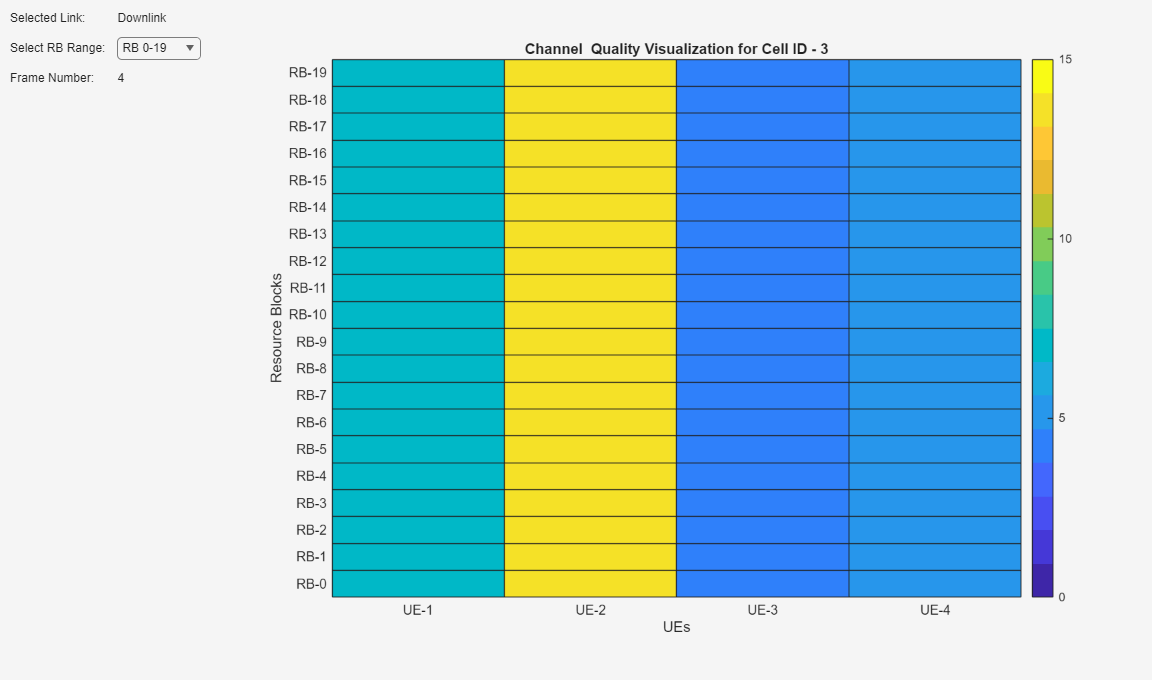

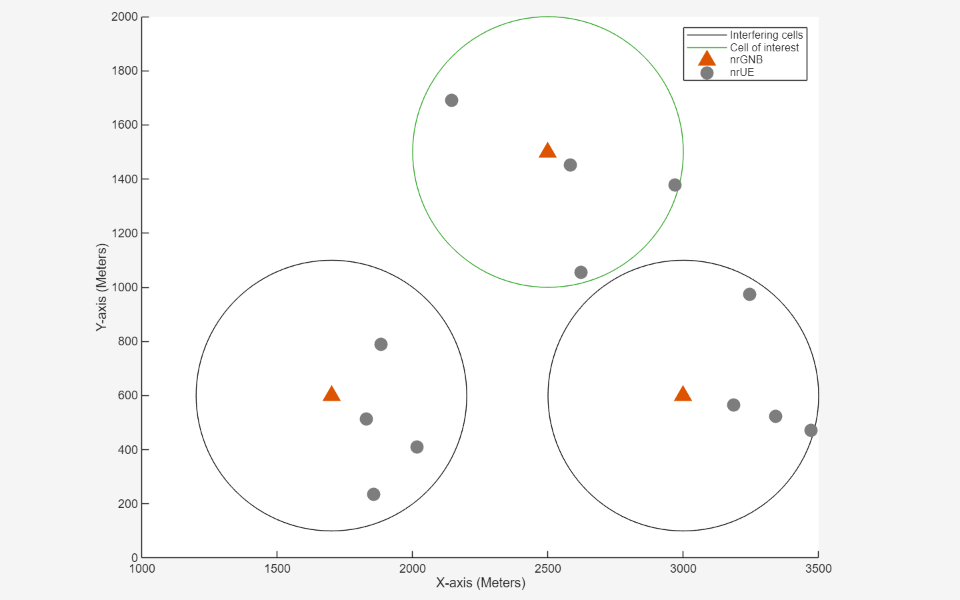

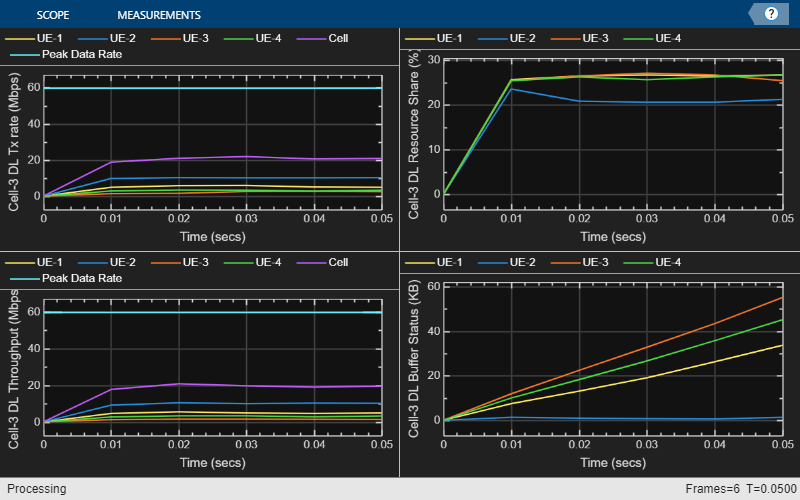

enableNetworkVisualization = true;
if enableNetworkVisualization
    % Create a visualizer to display the network
    networkVisualizer = helperNetworkVisualizer(SampleRate=1000);
    % Show the cell boundary of each gNB
    showBoundaries(networkVisualizer,gNBPositions,cellRadius,cellToAnalyze)
end

#### Run the simulation for the specified `numFrameSimulation` frames.

% Run the simulation
run(networkSimulator,simulationTime);

Peak DL throughput: 59.72 Mbps. Achieved cell DL throughput: 19.35 Mbps
Achieved DL throughput for each UE: [4.89        9.99        1.41        3.07]
Peak DL spectral efficiency: 5.97 bits/s/Hz. Achieved DL spectral efficiency for cell: 1.94 bits/s/Hz
Block error rate for each UE in the DL direction: [0.061           0       0.263           0]



displayPerformanceIndicators(metricsVisualizer)
path(p);

*Copyright 2020-2024 The MathWorks, Inc.*